# **Construct The Grid**

## **Dome**

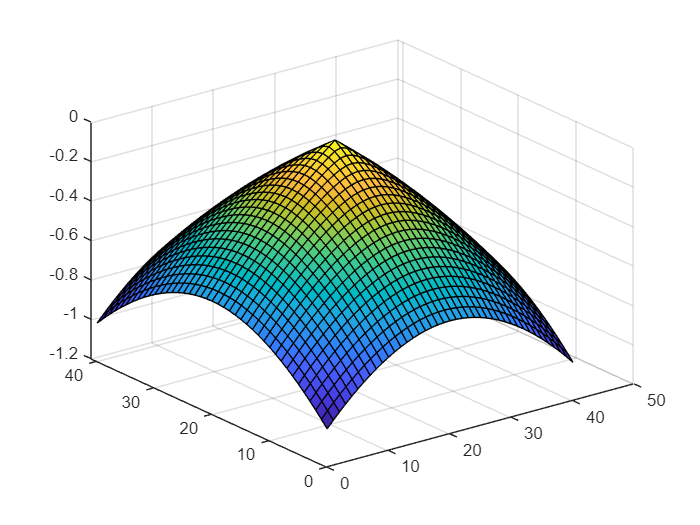

[xmax, ymax, n] = deal(1000, 1000, 40);
[x, y] = meshgrid(linspace(0, xmax, n+1), linspace(0, ymax, n+1));
dome = 1 - exp( sqrt( (x-xmax/2).^2 + (y-ymax/2).^2 ) *1e-3);
clf
surf(dome);

## **Add Some Perturbations**

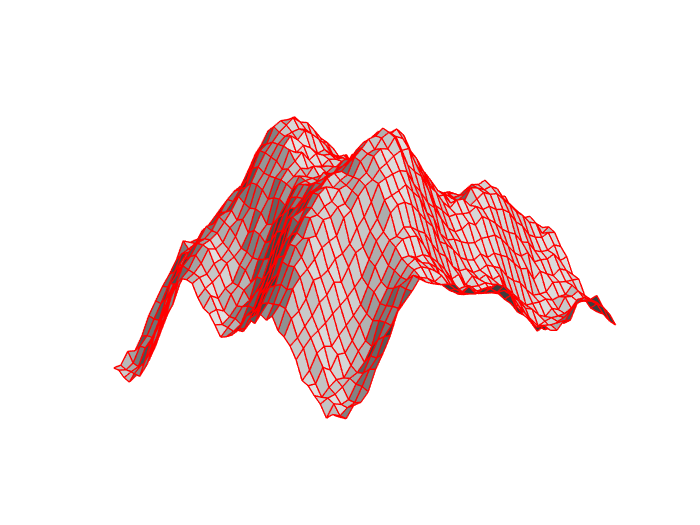

[xn, yn] = deal(pi*x/xmax, pi*y/xmax);
perturb = sin(5*xn) + 0.5*sin(4*xn + 6*yn) + cos(0.25*xn*yn./pi^2) + cos(3*yn);
perturb = perturb/3.5 ;
rng(0);
[h, hr] = deal(8, 1);
zt = 50 + h*perturb + hr*rand(size(x)) - 20*dome;


surf(x, y, zt - 0.2, 'EdgeColor', 'r', 'FaceColor', [0.8, 0.8, 0.8]); hold on
set(gca, 'ZDir', 'reverse');
view(50, 10); axis off; camlight; material dull; camproj('perspective');

## **Add Layers**

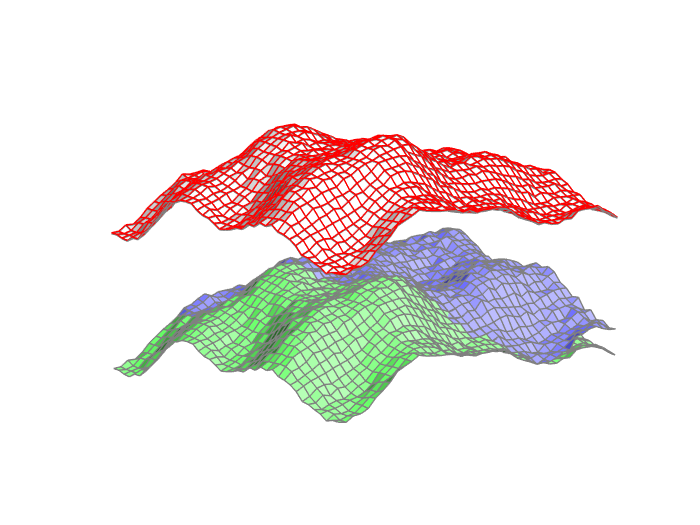

zb = zt + 30;
zmb = min(zb + 4 + 0.01*x - 0.02*y + hr*rand(size(x)), zb);

horizons = {struct('x', x', 'y', y', 'z', zt'), ...
            struct('x', x', 'y', y', 'z', zmb'), ...
            struct('x', x', 'y', y', 'z', zb')};
% Visualize

ht = surf(x, y, zt, 'EdgeColor',[0.5, 0.5, 0.5], 'FaceColor',[1, 0.4, 0.4]); hold on;
hm = surf(x, y, zmb, 'EdgeColor',[0.5, 0.5, 0.5], 'FaceColor',[0.4, 0.4, 1]);
hb = surf(x, y, zb, 'EdgeColor',[0.5, 0.5, 0.5], 'FaceColor',[0.4, 1 0.4]); hold off;

set(gca, 'ZDir', 'reverse');
view(50, 10); axis off; camlight; material dull; camproj('perspective');

## Construct The Layers

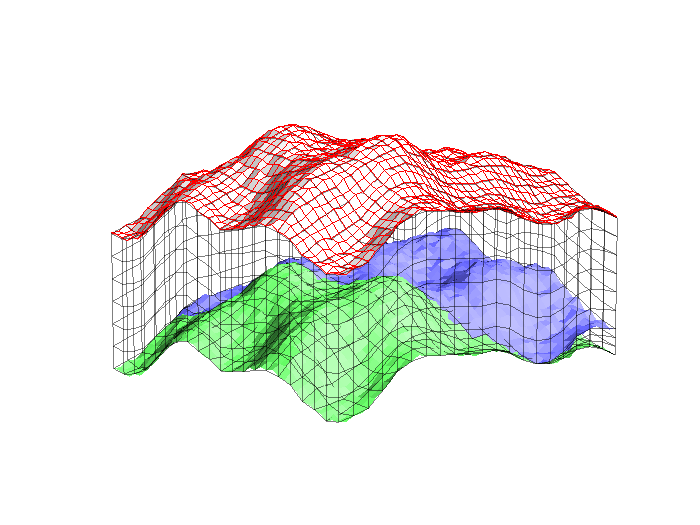

dims = [20, 20];
layers = [6 3];
grdecl = convertHorizonsToGrid(horizons, 'dims', dims, 'layers', layers);
G = processGRDECL(grdecl);


hold on
set([ht, hm, hb], 'Edgecolor', 'none');
plotGrid(G, 'facecolor', 'none', 'Edgealpha', 0.5);
hold off;

## **Add Faults**

[X, Y, Z] = buildCornerPtNodes(grdecl);
i = 47:80;
i = floor(i/2);
Z(i, :, :) = Z(i, :, :) + 0.022*min(0, Y(i, :, :)-550);
j = 1:30;  
j = ceil(j/2);
Z(:, j, :) = Z(:, j, :) + 0.021*min(0, X(:, j, :)-400);
j = 57:80; 
j = ceil(j/2);
Z(:, j, :) = Z(:, j, :) + 0.023*min(0, X(:, j, :)-750);
grdecl.ZCORN = Z(:);
G = processGRDECL(grdecl);
G = computeGeometry(G);

## Visualize Grid

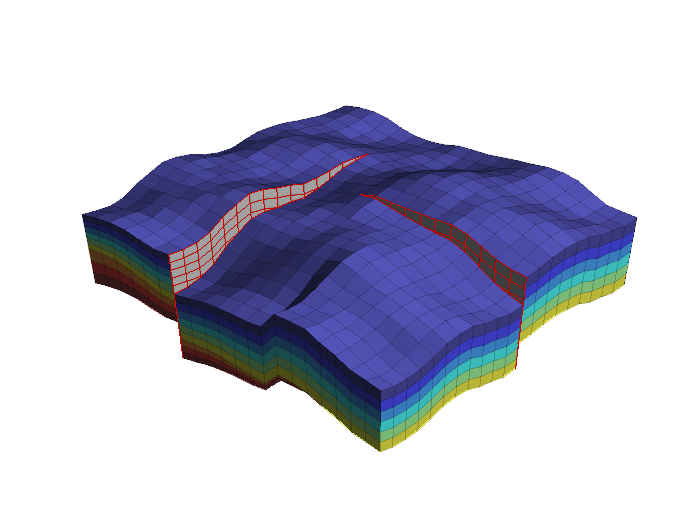

[~, ~, k] = gridLogicalIndices(G);
clf;
plotCellData(G, k, 'Edgealpha', 0.2); view(3);
plotFaces(G, find(G.faces.tag>0), 'Edgecolor', 'r', 'Facecolor', [0.8, 0.8, 0.8]);
colormap(0.7*jet + 0.3*ones(size(jet)));
axis off; camlight; material dull; camproj('perspective');

view([-48.7 56.8])

## Save Grd

save('C:\Users\user\Documents\MATLAB\Grid.mat', 'G');
